class 31/10

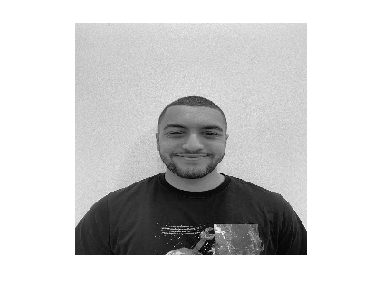

[o,luto]=imread('megray.tif');
y = o(256:-1:1,:);
y2 = o(:,256:-1:1);
imshow(o)

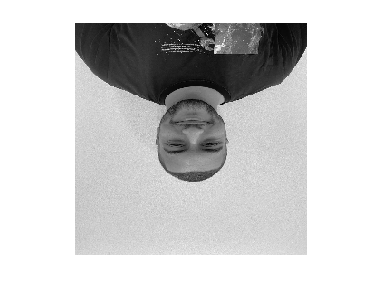

imshow(y)

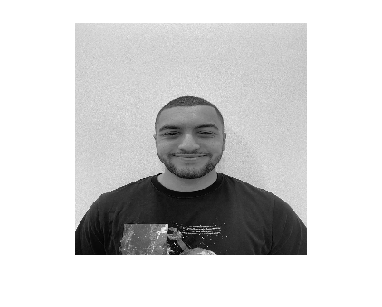

imshow(y2)

ayo

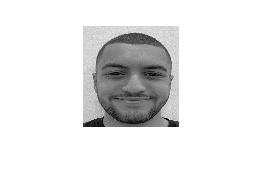

face = o(75:175,80:175);
imshow(face)

put face on all corners

[r c]=size(face)

r = 101

c = 96

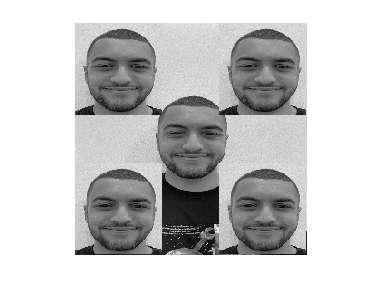

test=o;
test(1:101,1:96) = face;%top left
test(1:101,255-95:255) = face;%top right
test(255-100:255,1:96)=face;%bottom left
test(255-100:255,255-95:255)=face;%bottom right

imshow(test);

color of football

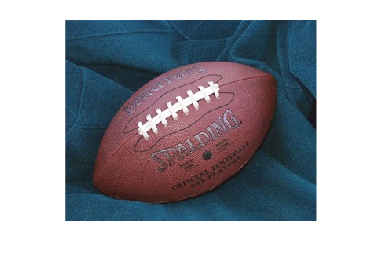

[f,lutf] = imread('football.jpg');
imshow(f);

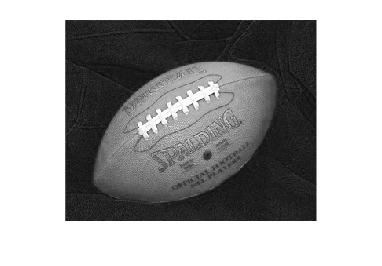

red = f(:,:,1);
green = f(:,:,2);
blue = f(:,:,3);

imshow(red);

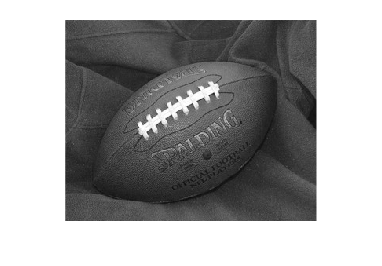

imshow(green);

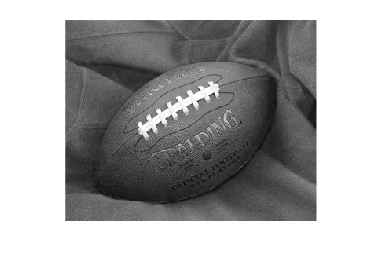

imshow(blue);

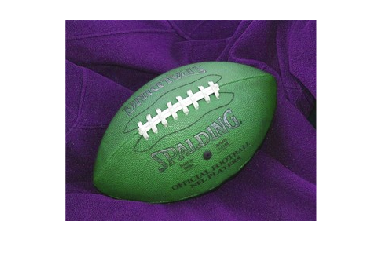


new(:,:,1)=green;
new(:,:,2)=red;
new(:,:,3)=blue;

imshow(new);

test = new;

Index in position 4 exceeds array bounds. Index must not exceed 1.

new appears to be both a function and a variable. If this is unintentional, use 'clear new' to remove the variable 'new' from the workspace.

imshow(test);
new_rg = new;
new_rb = new;
new_gb = new;

new_rg(:,:,3) = 0;
new_rb(:,:,2) = 0;
new_gb(:,:,1) = 0;

imshow(new_rg);
imshow(new_rb);
imshow(new_gb);